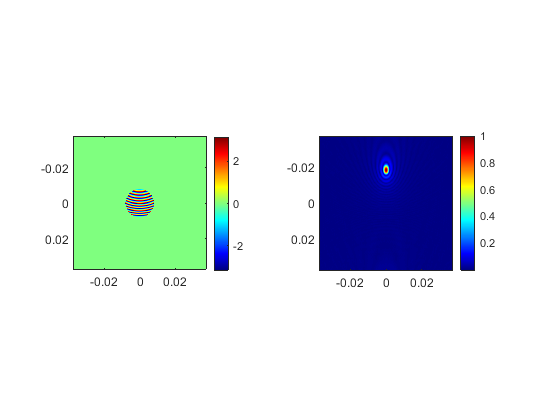

close all;

% add path to find function scripts
addpath('./Functions');

lambda = 1e-3;
k0 = 2*pi/lambda;
L = 0.075; % plane size
dimension = 0.016 ;% antenna dimension
M = 512;
dx = L/M;
z = 0.02;
x = dx*(-M/2:M/2-1);
y = dx*(-M/2:M/2-1);
[X, Y] = meshgrid(x, y);

angle_offset = 43;
offset = z*tand(angle_offset);


u0 = exp(1i*k0*sqrt(X.^2+(Y+offset).^2+z^2));
% u0(abs(y) > dimension/2, :) = 0;
% u0(:, abs(x)> dimension/2) = 0;

u0(X.^2+Y.^2 > (dimension/2)^2) = 0;

u1 = propTF(u0, L, lambda, z);

figure;
subplot(121);
imagesc(x, y, angle(u0));
colorbar;
axis square;
colormap jet;

subplot(122);
imagesc(x, y, abs(u1)/max(max(abs(u1))));
colorbar;
colormap jet;
axis square;